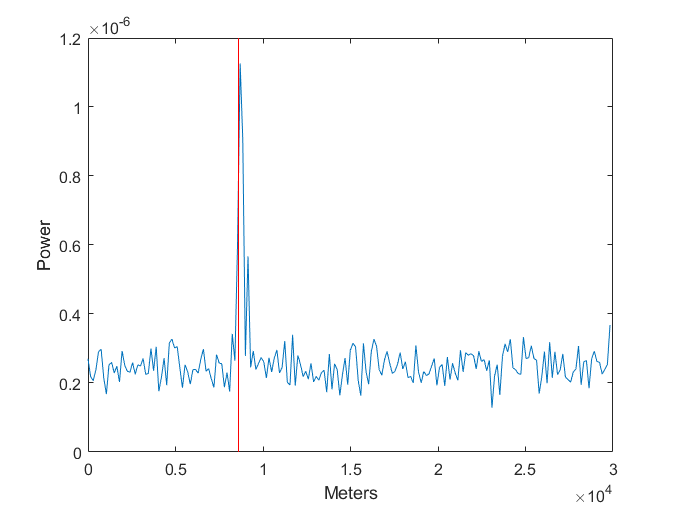

% Poveste
% Există o țintă cu o secțiune transversală radar nefluctuantă de 0,5 metri pătrați situată inițial la (7000,5000,0) .
% Ținta se deplasează cu un vector viteză constantă de (-15;-10;0) .
% Antena dumneavoastră transmite zece impulsuri dreptunghiulare cu o durată de 1 μs la o frecvență de repetiție a impulsurilor (PRF) de 5 kHz.
% Impulsurile se propagă către țintă, se reflectă în țintă, se propagă înapoi la antenă și sunt colectate de antenă.
% Antena funcționează într-un mod monostatic, primind doar atunci când emițătorul este inactiv.

% Pentru a crea forma de undă, utilizați phased.RectangularWaveformSystem object și setați proprietățile la valorile dorite.
waveform = phased.PhaseCodedWaveform('Code','Frank','NumChips',4,...
    'ChipWidth',1e-6,'PRF',5e3,'OutputFormat','Pulses',...
    'NumPulses',1);
tau = waveform.ChipWidth*waveform.NumChips;

% Pentru a modela antena, utilizați phased.IsotropicAntennaElementobiectul System.
% Setați frecvența de funcționare a antenei la (1,10) GHz. Antena izotropă radiază energie egală pentru unghiuri azimutale de la -180° la 180° și unghiurile de elevație de la -90° la 90°
antenna = phased.IsotropicAntennaElement('FrequencyRange',[1e9 10e9]);

% Pentru a modela ținta, utilizați phased.RadarTarget. 
% Ținta are un RCS nefluctuant de 0,5 metri pătrați, iar forma de undă incidentă pe țintă are o frecvență purtătoare de 4 GHz. 
% Forma de undă care reflectă ținta se propagă cu viteza luminii. Parametrizați aceste informații în definirea țintei dvs.
target = phased.RadarTarget('Model','Nonfluctuating',...
    'MeanRCS',0.5,'PropagationSpeed',physconst('LightSpeed'),...
    'OperatingFrequency',4e9);

% Pentru a modela locația și mișcarea antenei și a țintei, utilizați phased.Platform.
% Antena este staționară în acest scenariu și este situată la originea sistemului de coordonate global.
% Ținta este inițial situată la (7000,5000,0) și se mișcă cu un vector viteză constant de (-15,-10,0) .
transmitterplatform = phased.Platform('InitialPosition',[0;0;0],...
    'Velocity',[0;0;0]);
targetplatform = phased.Platform('InitialPosition',[7000; 5000; 0],...
    'Velocity',[-15;-10;0]); %pozitia initiala si viteza tintei

% Utilizați funcția rangeangle pentru a determina intervalul și unghiul dintre antenă și țintă
[tgtrng,tgtang] = rangeangle(targetplatform.InitialPosition,...
    transmitterplatform.InitialPosition);

% Pentru a modela specificațiile transmițătorului, utilizați phased.Transmitter.
% Un parametru cheie în modelarea unui transmițător este puterea de transmisie de vârf. 
% Pentru a determina puterea de transmisie de vârf, presupunem că probabilitatea dorită de detectare este 0,9 și probabilitatea maximă tolerabilă de alarmă falsă este 10^-6.
% Să presupunem că cele zece impulsuri dreptunghiulare sunt integrate necoerent la receptor.
% Puteți utiliza funcția "albersheim" pentru a determina raportul semnal-zgomot (SNR) necesar.
% SNR necesar este de aproximativ 5 dB. Să presupunem că doriți să setați puterea de transmisie de vârf pentru a obține SNR-ul necesar pentru ținta dvs. la o rază de până la 15 km. Să presupunem că transmițătorul are un câștig de 20 dB.  
% Utilizați ecuația radar pentru a determina puterea de transmisie de vârf necesară.
numpulses = 10; %cate impulsuri transmit
Pd = 0.9;
Pfa = 1e-6;
maxrange = 1.5e4; %15km
lambda = physconst('LightSpeed')/target.OperatingFrequency;
RCS = 0.5;
Ts = 290;
SNR = albersheim(Pd,Pfa,10);
Gain = 20; %castig transmitator 20dB
dbterms = db2pow(SNR - 2*Gain);
Pt = (4*pi)^3*physconst('Boltzmann')*Ts/tau/RCS/(lambda^2)*maxrange^4*dbterms;


% Utilizați o putere de vârf de 50 de kilowați în modelarea transmițătorului.
% Pentru a menține o fază constantă în formele de undă ale pulsului, setați CoherentOnTransmit la true.
% Deoați transmițătorul întarece utilizr-un mod monostatic (transmisie-recepție), setați InUseOutputPort la true pentru a înregistra starea emițătorului.
transmitter = phased.Transmitter('PeakPower',50e3,'Gain',20,...
    'LossFactor',0,'InUseOutputPort',true,...
    'CoherentOnTransmit',true);

% Pentru a modela radiația formei de undă din matrice, utilizați phased.
% Radiatorobiectul System. Pentru a modela colectarea semnalelor în bandă îngustă la matrice, utilizați phased.Collector.
% Pentru colectarea semnalului de bandă largă, utilizați phased.WidebandCollectorobiectul System.
% În acest exemplu, pulsul satisface ipoteza semnalului de bandă îngustă.  
% Frecvența purtătoare este de 4 GHz.
% Pentru valoarea Sensorproprietății, utilizați handleul pentru antena izotropă.
% În phased.Collector, setați Wavefront la 'Plane'pentru a specifica că forma de undă incidentă de pe antenă este o undă plană.
radiator = phased.Radiator('Sensor',antenna,...
    'PropagationSpeed',physconst('LightSpeed'),...
    'OperatingFrequency',4e9);
collector = phased.Collector('Sensor',antenna,...
    'PropagationSpeed',physconst('LightSpeed'),...
    'Wavefront','Plane','OperatingFrequency',4e9);

% Pentru a modela receptorul, utilizați phased.ReceiverPreamp.
% În receptor, specificați cifra de zgomot și temperatura de referință, care contribuie la zgomotul intern al sistemului dumneavoastră.
% În acest exemplu, setați cifra de zgomot la 2 dB și temperatura de referință la 290 Kelvin.
% Setați generatorul de numere aleatoare la o valoare fixă ��pentru rezultate reproductibile.
receiver = phased.ReceiverPreamp('Gain',20,'NoiseFigure',2,...
    'ReferenceTemperature',290,'SampleRate',1e6,...
    'EnableInputPort',true,'SeedSource','Property','Seed',1e3);

% Pentru a modela mediul de propagare, utilizați phased.FreeSpace.
% Puteți modela propagarea unidirecțională sau dublă prin setarea TwoWayPropagationproprietății.
% În acest exemplu, setați această proprietate la false pentru a modela propagarea unidirecțională.
channel = phased.FreeSpace(...
    'PropagationSpeed',physconst('LightSpeed'),...
    'OperatingFrequency',4e9,'TwoWayPropagation',false,...
    'SampleRate',1e6);

% Pregatim bucla principala de simulare.
T = 1/waveform.PRF;
txpos = transmitterplatform.InitialPosition;

rxsig = zeros(waveform.SampleRate*T,numpulses);
for n = 1:numpulses
     % Actualizați poziția țintă
    [tgtpos,tgtvel] = targetplatform(T);
     % Obțineți intervalul și unghiul față de țintă
    [tgtrng,tgtang] = rangeangle(tgtpos,txpos);
     % Generați pulsul
    sig = waveform();
     % Transmite pulsul. Starea transmițătorului de ieșire
    [sig,txstatus] = transmitter(sig);
     % Radiază pulsul către țintă
    sig = radiator(sig,tgtang);
     % Propagați pulsul către țintă în spațiul liber
    sig = channel(sig,txpos,tgtpos,[0;0;0],tgtvel);
      % Reflectați pulsul de pe țintă
    sig = target(sig);
     % Propagați ecoul către antenă în spațiul liber
    sig = channel(sig,tgtpos,txpos,tgtvel,[0;0;0]);
     % Colectați ecoul din unghiul incident la antenă
    sig = collector(sig,tgtang);
     % Primiți ecoul la antenă când nu transmiteți
    rxsig(:,n) = receiver(sig,~txstatus);
end

% Integrați în mod necoerent ecourile primite, creați un vector de porți de gamă și trasați rezultatul.
% Linia roșie verticală de pe diagramă marchează intervalul țintei.
rxsig = pulsint(rxsig,'noncoherent');
t = unigrid(0,1/receiver.SampleRate,T,'[)');
rangegates = (physconst('LightSpeed')*t)/2;
plot(rangegates,rxsig)
hold on
xlabel('Meters'); ylabel('Power')
ylim = get(gca,'YLim');
plot([tgtrng,tgtrng],[0 ylim(2)],'r')
hold off